Digital Signal Processing Lab (EE-384L)

# Assignment No. 6:   **Multirate Signal Processing**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Consider the transfer function of a notch filter, 


$$H\left(z\right)\;=\;\frac{1+a}{2}\;\frac{\left(z-e^{j\omega_n } \right)\left(z-e^{-j\omega_n } \right)}{\left(z-{a\;e}^{j\omega_n } \right)\left(z-{a\;e}^{-j\omega_n } \right)}$$


where $\omega_n$ is the frequency to be stopped. This system has two zeros (at $\omega_n$ and $-\omega_n$). Sampling rate = $F_s$.

**Question (1):**

Read $\mathrm{almostcaught}\_\mathrm{high}\ldotp \mathrm{wav}$, and examine using DTFT to figure out frequency of tone present in the audio.

**Answer (1):**

The code, along with the results (inline), to read & compute DTFT of this audio starts below.

***Note:***  The $\textrm{dtft}\_\textrm{split}\left(\right)$, $\textrm{plotMagPhase}\left(\right)$, $\textrm{dnsample}\left(\right)$, and $\textrm{sigadd}\left(\right)$ functions used in different tasks have been defined at end of report.

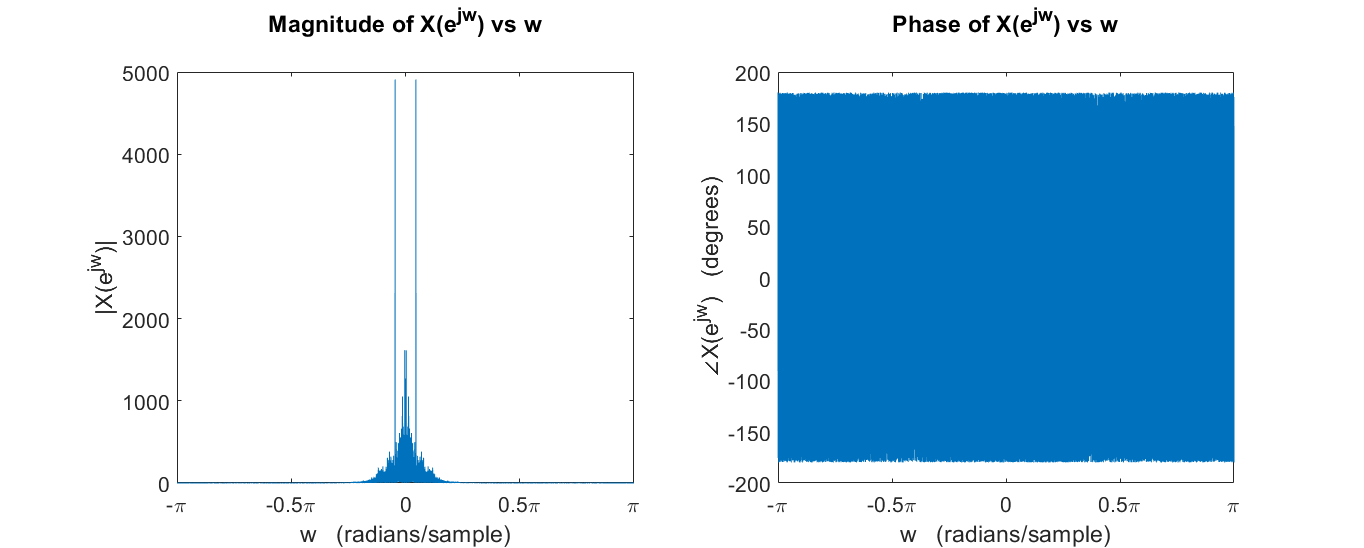

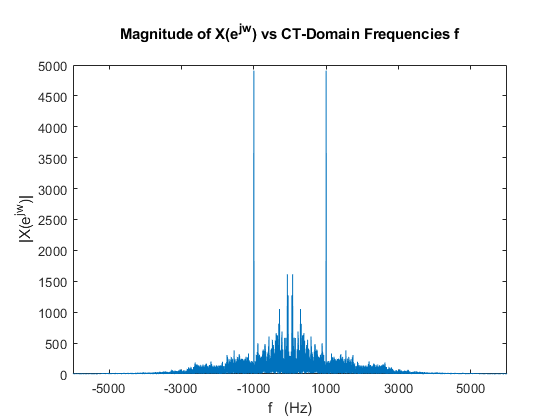

% <task> read and play the provided almostcaught_high.wav file

% read audio data from .wav file (255864×1 double i.e. 1 channel audio)
[x, Fs] = audioread('almostcaught_high.wav');

% get and play the audio x(t) using sound command, using audio's Fs
sound(x, Fs);                               pause((length(x)-1)/Fs);

% <task> plot DTFT of sound data

% initialize frequency vector (and other vars) for computing DTFT X(w)
w = -pi:2*pi/(length(x)-1):pi;              % for 1 period [-pi, pi] or DTFT
f = Fs * w/(2*pi);                          % corresponding CT-domain frequencies
x = x.';                                    % convert x[n] to row-vector
n = 0:(length(x)-1);                        % assuming audio starts at n=0

% compute DTFT X(w) using (chunk-wise) matrix-multipication method
if isfile("T1_Xw.mat") load("T1_Xw.mat"); end
if ~exist('Xw','var')
    Xw = dtft_split(x, n, w, 750);          save("T1_Xw.mat",'Xw');
end

% obtain magnitude and phase (in degrees) of DTFT X(w)
Xw_mag = abs(Xw);       Xw_ang = angle(Xw)*180/pi;

% plot mag. and phase of DTFT X(w) vs w, and mag. of X(w) vs CT-domain frequencies f
plotMagPhase(w, Xw_mag, Xw_ang, 'X', f);

The sampling frequency $F_s$ of the given audio sequency is $44100\;\textrm{samples}/\sec$. This means that the range $\omega =\left\lbrack -\pi \;,\;\pi \;\right\rbrack \;\textrm{rad}/\sec$ maps to the CT frequency-range, 


$$f\;=\;\frac{\Omega }{2\pi }\;=\;\left\lbrack -\frac{F_s }{2},\;\frac{F_s }{2}\right\rbrack \;=\;\left\lbrack -22050,\;22050\right\rbrack \;\textrm{Hz}$$


The sharp tone is visible in the DTFT magintude at exactly $f=\pm 1\;\mathrm{kHz}$ (CT) or at $\omega =0\ldotp 04535\pi \;\mathrm{rad}/\sec$ (DT), as,


$$\omega \;=\;\Omega \mathrm{T}\;=\;2\pi \left(f\right)\frac{1}{F_s }\;=\;2\frac{\left(1000\right)}{44100}\pi \;=\;0\ldotp 04535\pi \;\mathrm{rad}/\sec$$


**Question (2):**

Design a notch filter using mentioned transfer function $H\left(z\right)$ and remove the tone.

**Answer (2):**

As found in Q1, the tone is present at $\omega =0\ldotp 04535\pi \;\textrm{rad}/\sec$. Hence, this will be the frequency to be stopped ($\omega_n$) by $H\left(z\right)$:


$$H\left(z\right)\;=\;\frac{1+a}{2}\;\frac{\left(z-e^{j\;0\ldotp 04535\pi } \right)\left(z-e^{-j\;0\ldotp 04535\pi } \right)}{\left(z-{a\;e}^{j\;0\ldotp 04535\pi } \right)\left(z-{a\;e}^{-j\;0\ldotp 04535\pi } \right)}$$


The code, along with the results, to declare this Notch-Filer and use it to remove the tone, starts below.

% <task> identify tone (here, at max amplitude) frequency precisely

% get frequency of max amplitude (tone) present in DTFT of audio
wn = abs(w(find(Xw_mag==max(Xw_mag), 1)));
disp(['The tone is at ωn = ', num2str(round(wn/pi, 5)), 'π.']);

The tone is at ωn = 0.04535π.



% <task> design Notch Filter corresponding to wn = tone frequency

% define H(z) symbolically
syms z;
a = 0.75;
Hz = ((1+a)/2) * ((z-exp(1i*wn))*(z-exp(-1i*wn))) / ((z-a*exp(1i*wn))*(z-a*exp(-1i*wn)));

% simplify expression to get unfactored form
Hz = vpa(simplify(Hz), 5)

$$Hz = \frac{9.0865e+33\,z^{2}-1.7989e+34\,z+9.0865e+33}{1.0385e+34\,z^{2}-1.5419e+34\,z+5.8413e+33}$$

This result can be expressed as a fraction of polynomials in terms of $z^{-1}$, as follows:


$$\begin{array}{l}
H\left(z\right)\;=\;\frac{z^{-2} }{z^{-2} }\;\frac{9.0865\times {10}^{33} \,z^2 -1.7989\times {10}^{34} \,z+9.0865\times {10}^{33} }{1.0385\times {10}^{34} \,z^2 -1.5419\times {10}^{34} \,z+5.8413\times {10}^{33} }\\
\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{9.0865\,-17\ldotp 989\,z^{-1} +9.0865\;z^{-2} }{10\ldotp 385\,-15\ldotp 419\,z^{-1} +5.8413\;z^{-2} }\\
\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{0\ldotp 875\,-1\ldotp 7323\,z^{-1} +0\ldotp 875\;z^{-2} }{1\,-1\ldotp 4848\,z^{-1} +0\ldotp 5625\;z^{-2} }\\
\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{b_0 {\;z}^0 \,+b_1 \,z^{-1} +b_2 \;z^{-2} }{a_0 \,z^0 +a_1 \,z^{-1} +a_2 \;z^{-2} }
\end{array}$$


which gives the following CCDE coefficients:


$$\begin{array}{l}
b\;=\;\left\lbrace \;0\ldotp 875,\;-1\ldotp 7323,\;0\ldotp 875\;\right\rbrace \\
a\;=\;\left\lbrace \;1,\;-1\ldotp 4848,\;0\ldotp 5625\;\right\rbrace 
\end{array}$$


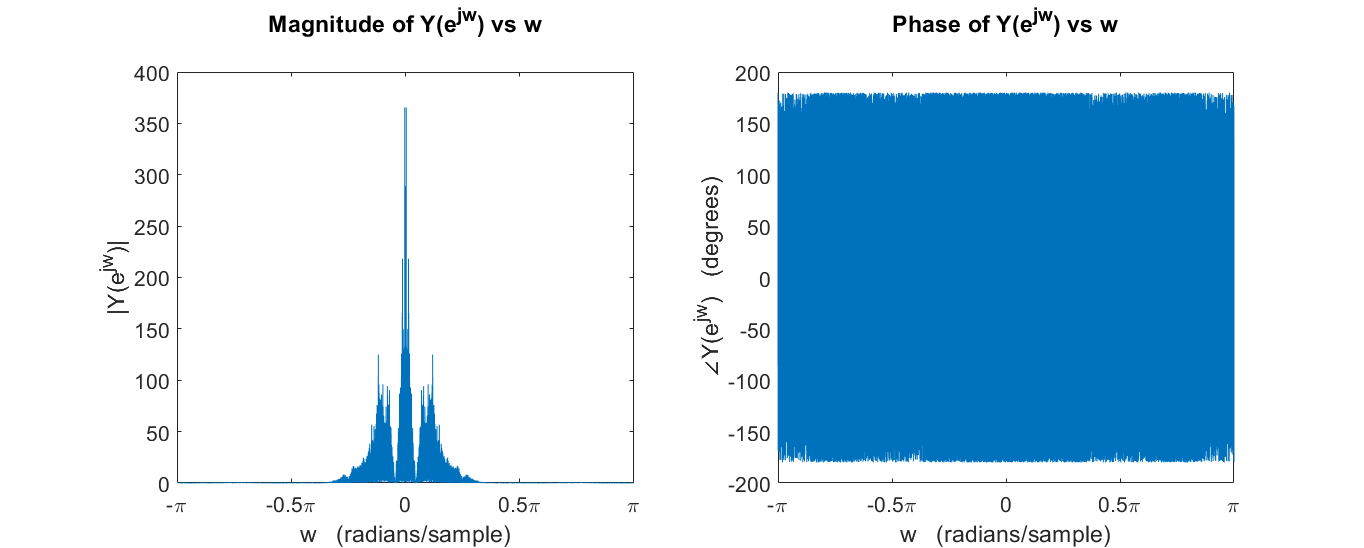

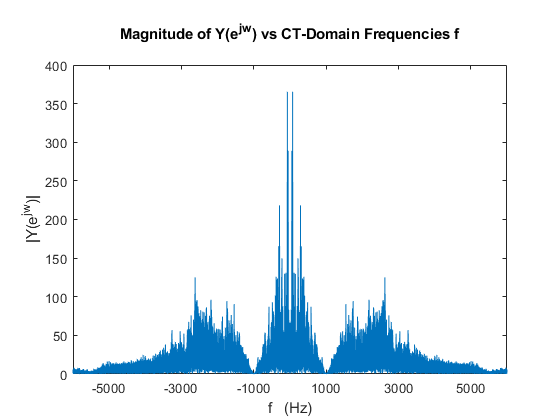


% define Notch Filter system's CCDE coefficients
b = [0.875 -1.7323 0.875];
a = [1 -1.4848 0.5625];

% <task> remove the tone in x[n] by passing it through Notch Filter

% assuming zero initial conditions (rest)
N_aux = zeros(1, length(a)-1);
M_init = zeros(1, length(b)-1);

% compute system output y[n] for 0 <= n < length(x), with input = sound data x[n],
% using get_system_out()
[y, ny] = get_system_out(b, a, x, N_aux, M_init);
duration = (length(y)-1)/Fs;

% get and play the audio y(t) using sound command, using audio's Fs
sound(y, Fs);
% pause execution while the sound is playing
pause(duration);

% <task> plot DTFT of sound data after passing through system (DTFT of y[n])

% initialize frequency vector (and other vars) for computing DTFT Y(w)
w = -pi:2*pi/(length(y)-1):pi;              % for 1 period [-pi, pi] or DTFT
f = Fs * w/(2*pi);                          % corresponding CT-domain frequencies

% compute DTFT Y(w) using (chunk-wise) matrix-multipication method,
% since this is a large computation, avoid repeating it if already computed
if isfile("T1_Yw.mat") load("T1_Yw.mat"); end
if ~exist('Yw','var')
    Yw = dtft_split(y, ny, w, 750);
    save("T1_Yw.mat",'Xw');
end

% obtain magnitude and phase of DTFT Y(w)
Yw_mag = abs(Yw);                           % get the magnitude of Y(w)
Yw_ang = angle(Yw)*180/pi;                  % get the phase (angle) of Y(w) in degrees

% plot magnitude and phase of DTFT Y(w) vs w, 
% and magnitude of Y(w) vs CT-domain frequencies f
plotMagPhase(w, Yw_mag, Yw_ang, 'Y', f);

***Note:***  Compared to the (CT-frequency) plot of $\left|X\left(e^{j\omega } \right)\right|$, this plot of $\left|Y\left(e^{j\omega } \right)\right|$ is zoomed in on the y-axis.

**Question (3):**

How many multiplications and additions are required per unit time for the filter?

**Answer (3):**

Given its CCDE coefficients, this Notch Filter system can be represented as,


$$H\left(z\right)\;=\;\frac{\;0\ldotp 875-1\ldotp 7323\,z^{-1} +0\ldotp 875\;z^{-2} }{1-1\ldotp 4848\,z^{-1} +0\ldotp 5625\;z^{-2} }\;=\;\frac{Y\left(z\right)}{X\left(z\right)}$$


which translates to the following CCDE,


$$y\left\lbrack n\right\rbrack -1\ldotp 4848y\left\lbrack n-1\right\rbrack +0\ldotp 5625y\left\lbrack n-2\right\rbrack \;=\;0\ldotp 875x\left\lbrack n\right\rbrack -1\ldotp 7323x\left\lbrack n-1\right\rbrack +0\ldotp 875x\left\lbrack n-2\right\rbrack$$



$$y\left\lbrack n\right\rbrack \;=\;1\ldotp 4848y\left\lbrack n-1\right\rbrack -0\ldotp 5625y\left\lbrack n-2\right\rbrack +0\ldotp 875x\left\lbrack n\right\rbrack -1\ldotp 7323x\left\lbrack n-1\right\rbrack +0\ldotp 875x\left\lbrack n-2\right\rbrack$$


Since the output-computing function $\textrm{get}\_\textrm{system}\_\textrm{out}\left(\right)$ is essentially using above CCDE representation of the filter to compute output $y\left\lbrack n\right\rbrack$, this CCDE gives us the estimate of multiplications and additions done per sample. Assuming $a_0 =1$, the multiplication of above R.H.S. with ($1/a_0$) is not necessary, which leaves us with,

$5\;\mathrm{multiplications}$,          and          $4\;\textrm{additions}$,          per sample of $y\left\lbrack n\right\rbrack$.

With $F_s =44100\;\textrm{samples}/\sec$, new samples of $x\left\lbrack n\right\rbrack$ arrive at a rate of $44100\;\textrm{samples}/\sec$, resulting in,

$5\times 44100\;=\;220500\;\mathrm{multiplications}$,   and

$\;\;\;\;4\times 44100\;=\;176400\;\mathrm{additions}$   per second.

*Next task starts from the next page.*

## Task 2

**Statement:**

Now, we'll redo Task 1 but on a decimated version of input signal. Consider the system below:

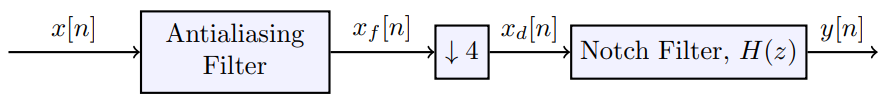

**Question (1):**

Design a lowpass FIR filter, using MATLAB’s $\textrm{fir1}$ command, for antialiasing. The length of the filter should be $23$.

**Answer (1):**

The $\textrm{fir1}$ command has the following syntax,


$$\mathrm{b}=\textrm{fir1}\left(n,\omega_n \right)$$
 

which uses a Hamming window to design an $n$th-order lowpass filter when $\omega_n$ ($=\omega_{\textrm{cutoff}} /\pi$) is a single value. Since we're decimating $x\left\lbrack n\right\rbrack$ by $M=4$, the AA filter cutoff should be $\pi /M=\pi /4$. The order $n$ would be $\left(\mathrm{length}-1\right)=N-1$. So we have,


$$\begin{array}{l}
\;\;n\;=\;23-1=22\\
\omega_n \;=\;\frac{\pi /4}{\pi }\;=\;\frac{1}{4}
\end{array}$$


The code, along with the results (inline), to design this antialiasing filter starts below.

% <task> design a lowpass FIR filter for antialiasing

M = 4;                                      % decimation factor
AA_N = 23;                                  % AA filter length
AA_n = AA_N-1;                              % AA filter order
AA_wn = 1/M;                                % AA filter cutoff/pi

% design low-pass filter for antialiasing using fir(N, wn) command
hlp = fir1(AA_n, AA_wn);
nhlp = 0:(length(hlp)-1);

**Question (2):**

Plot the impulse response as well as the frequency response of the lowpass FIR filter. 

Do you recognize the impulse response? Which function does it resemble and why?

**Answer (2):**

The code to plot the impulse & frequency response of the AA filter starts below.

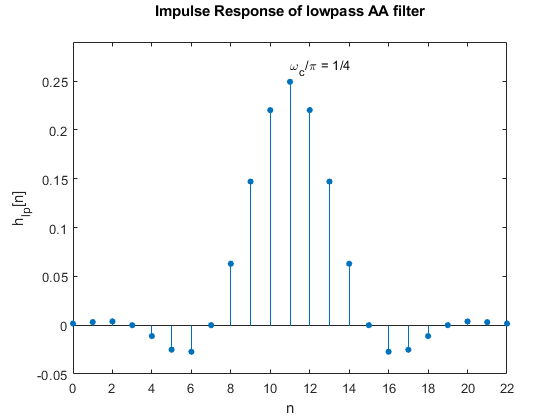

% <task> plot impulse response hlp[n] of the FIR lowpass AA filter

fig = figure;
stem(nhlp, hlp, 'filled', 'MarkerSize', 4);
xlabel('n'); ylabel('h_{lp}[n]'); 
xlim([min(nhlp) max(nhlp)]); 
ylim([-0.05 0.29]);
title({"Impulse Response of lowpass AA filter";''});
text(nhlp(find(hlp==max(hlp), 1)), max(hlp)+0.015, '\omega_c/\pi = 1/4');

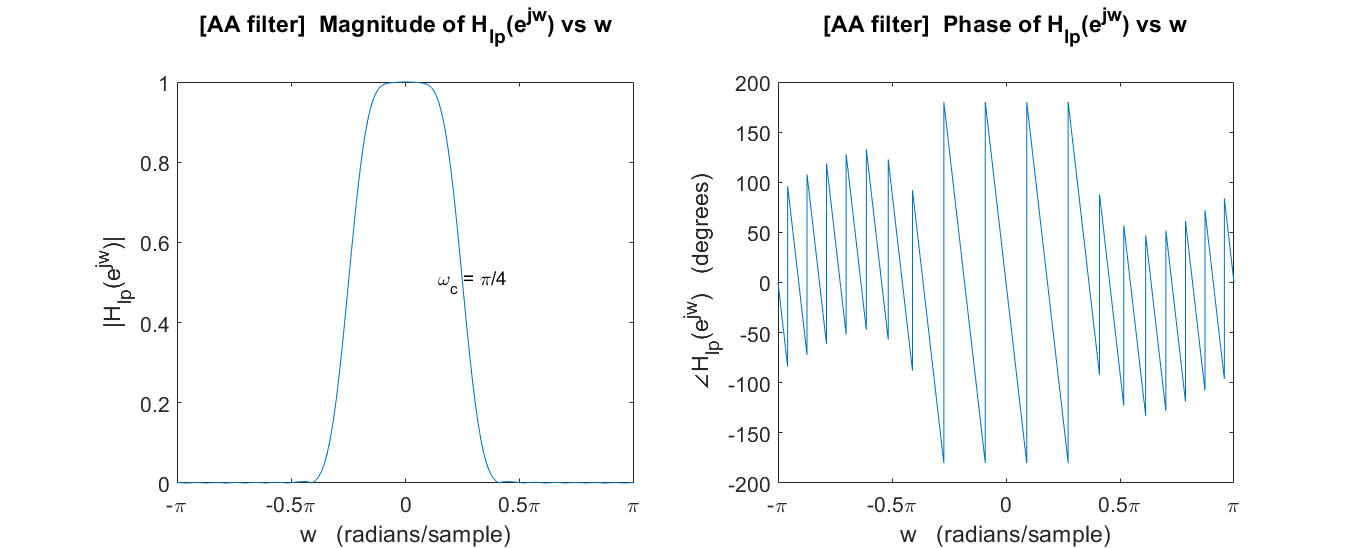


% <task> plot frequency response Hlp(w) of the FIR lowpass AA filter

% initialize frequency vector for computing DTFT Hlp(w)
w = -pi:2*pi/(length(y)-1):pi;              % for 1 period [-pi, pi] or DTFT

% compute DTFT Hlp(w) using matrix-multipication method
Hlpw = hlp * exp(-1i * nhlp' * w);

% obtain magnitude and phase of DTFT Hlp(w)
Hlpw_mag = abs(Hlpw);                       % get the magnitude of Hlp(w)
Hlpw_ang = angle(Hlpw)*180/pi;              % get the phase (angle) of Hlp(w) in degrees

% plot magnitude and phase of DTFT Hlp(w)
fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 1]);

% plot magnitude of Hlp(w) vs w
subplot(1, 2, 1);
plot(w, Hlpw_mag);
xlabel('w   (radians/sample)'); ylabel('|H_{lp}(e^{jw})|'); 
title({'[AA filter]  Magnitude of H_{lp}(e^{jw}) vs w';''}, 'FontSize', 16);
setDTFTradialAxis(1); 
text(wn*pi, 0.5, '\omega_c = \pi/4', 'FontSize', 14);
ax = gca; ax.FontSize = 16;

% plot phase of Hlp(w) vs w
subplot(1, 2, 2);
plot(w, Hlpw_ang);
xlabel('w   (radians/sample)'); ylabel('∠H_{lp}(e^{jw})   (degrees)');
title({'[AA filter]  Phase of H_{lp}(e^{jw}) vs w';''}, 'FontSize', 16);
setDTFTradialAxis(1); 
ax = gca; ax.FontSize = 16;

The impulse response of the lowpass AA filter is a $\textrm{sinc}$ function, given by $\sin \left(\omega_c \;n\right)/\pi n$, which equals $\omega_c /\pi$ for $n=0$ (but $h_{\textrm{lp}} \left\lbrack n\right\rbrack$ has been assumed to start at $n=0$). The Fourier Transform of this $\textrm{sinc}$ function, which gives the Frequency Response of the filter, is,


$$h_{\textrm{lp}} \left\lbrack n\right\rbrack \;=\;\frac{\sin \left(\omega_c \;n\right)}{\pi \;n}\;\;\;\;\;\iff \;\;\;\;\;H_{\textrm{lp}} \left(e^{j\omega } \right)=$$
 
$$
    \begin{cases}
      1, & |\omega| <\omega_c \\
      0, & \omega_c <|\omega|\leq\pi\\
    \end{cases} $$


which is a gate ($\Pi$) function. This is the typical response of a lowpass filter where frequencies below $\pm \;\omega_c$ are allowed to pass with gain $1$, while higher frequencies are blocked. In our case, $\omega_c =\frac{\pi }{M}=\frac{\pi }{4}$.

**Question (3):**

Implement this (decimated) system in MATLAB. 

How many additions and multiplications are required for this system per unit time?

**Answer (3):**

The code implementing the system with decimated $x\left\lbrack n\right\rbrack$ starts below.

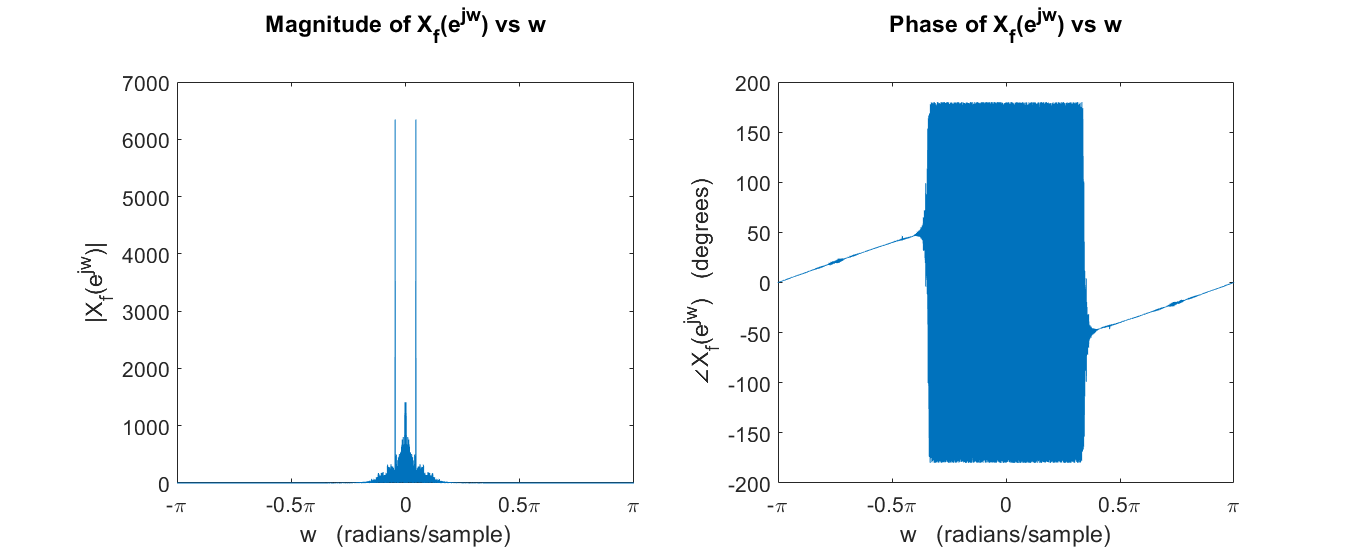

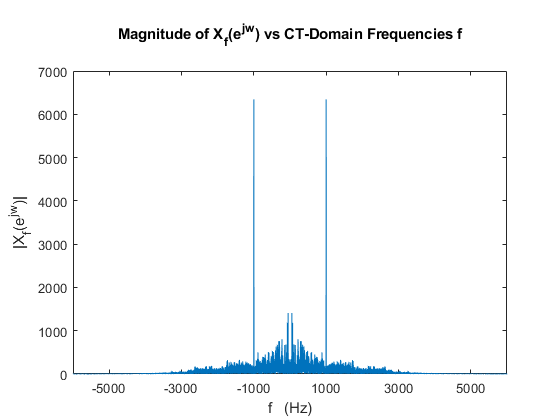

% <stage 1> pass x[n] through lowpass AA filter to get xf[n]

% CCDE coefficients for the AA filter
b = hlp;
a = [1];

% assuming zero initial conditions (rest)
N_aux = zeros(1, length(a)-1);
M_init = zeros(1, length(b)-1);

% pass x[n] through hlp[n] to get xf[n],
% using get_system_out()
[xf, nxf] = get_system_out(b, a, x, N_aux, M_init);

% compute and plot DTFT of xf[n]

% initialize frequency vector (and other vars) for computing DTFT X(w)
w = -pi:2*pi/(length(xf)-1):pi;             % for 1 period [-pi, pi] or DTFT
f = Fs * w/(2*pi);                          % corresponding CT-domain frequencies

% compute DTFT Xf(w) using (chunk-wise) matrix-multipication method,
% since this is a large computation, avoid repeating it if already computed
if isfile("T2_Xfw.mat") load("T2_Xfw.mat"); end
if ~exist('Xfw','var')
    Xfw = dtft_split(xf, nxf, w, 750);
    save("T2_Xfw.mat",'Xfw');
end

% obtain magnitude and phase of DTFT Xf(w)
Xfw_mag = abs(Xfw);                         % get the magnitude of Xf(w)
Xfw_ang = angle(Xfw)*180/pi;                % get the phase (angle) of Xf(w) in degrees

% plot magnitude and phase of DTFT Xf(w) vs w, 
% and magnitude of Xf(w) vs CT-domain frequencies f
plotMagPhase(w, Xfw_mag, Xfw_ang, 'X_f', f);

Here, the frequency content higher than,


$$\begin{array}{l}
f\;=\;\pm \frac{{\;\omega }_c }{2\pi \mathrm{T}}\;=\;\pm \frac{\pi /4}{2\pi \left(1/44100\right)}\\
\;\;\;\;=\;\pm 5512\ldotp 5\;\mathrm{Hz}\;\\
\;\;\;\;\approx \;\pm 5\ldotp 5\;\mathrm{kHz}
\end{array}$$
 

has been removed by the antialiasing filter.

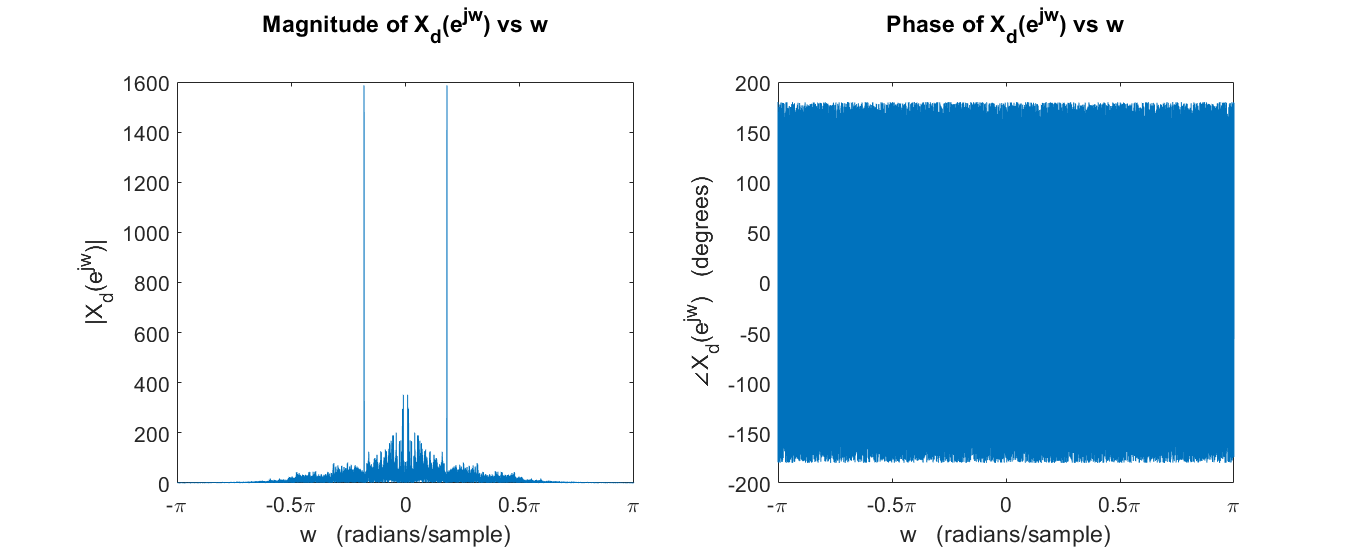

% <stage 2> downsample xf[n] by M=4 to get xd[n]

% downsample xf[n] to get xd[n]=xf[nM]
M = 4;                                      % decimation factor
[xd, nxd] = dnsample(xf, nxf, M);

% compute and plot DTFT of xd[n]

% initialize frequency vector (and other vars) for computing DTFT X(w)
w = -pi:2*pi/(length(xd)-1):pi;             % for 1 period [-pi, pi] or DTFT

% compute DTFT Xd(w) using (chunk-wise) matrix-multipication method,
if isfile("T2_Xdw.mat") load("T2_Xdw.mat"); end
if ~exist('Xdw','var')
    Xdw = dtft_split(xd, nxd, w, 750);      save("T2_Xdw.mat",'Xdw');
end

% obtain magnitude and phase (in degrees) of DTFT Xd(w)
Xdw_mag = abs(Xdw);     Xdw_ang = angle(Xdw)*180/pi;

% plot magnitude and phase of DTFT Xd(w) vs w
plotMagPhase(w, Xdw_mag, Xdw_ang, 'X_d');

Decimation by $4$ is equivalent to multiplying $\omega$ axis by $4$, shifting by $2\pi i$ ($i\;=\left\lbrack 0,1,2,3\right\rbrack$) to get $4$ spectrums, and summing them. As a result, the spectrum plot here, over $\left\lbrack -\pi ,\;\pi \right\rbrack$, has expanded in $\omega$ by $4$.

Now the tone has shifted to a new DT frequency $\omega =4\left(\pm \;0\ldotp 04535\pi \right)\;=\pm \;0\ldotp 1814\pi \;\textrm{rad}/\sec$. Hence, this will be the new frequency to be stopped ($\omega_n$) by Notch Filter $H\left(z\right)$:


$$H\left(z\right)\;=\;\frac{1+a}{2}\;\frac{\left(z-e^{j\;0\ldotp 1814\pi } \right)\left(z-e^{-j\;0\ldotp 1814\pi } \right)}{\left(z-{a\;e}^{j\;0\ldotp 1814\pi } \right)\left(z-{a\;e}^{-j\;0\ldotp 1814\pi } \right)}$$


% <stage 3> pass xd[n] through Notch Filter to remove the tone

% identify tone (at max amplitude) freq. precisely from (decimated) audio DTFT Xd(w)
wn = abs(w(find(Xdw_mag==max(Xdw_mag), 1)));
disp(['Now, the tone is at ωn = ', num2str(round(wn/pi, 5)), 'π.']);

Now, the tone is at ωn = 0.1814π.



% design Notch Filter corresponding to wn = tone frequency
syms z;
a = 0.75;
Hz = ((1+a)/2) * ((z-exp(1i*wn))*(z-exp(-1i*wn))) / ((z-a*exp(1i*wn))*(z-a*exp(-1i*wn)));
Hz = vpa(simplify(Hz), 5)

$$Hz = \frac{5.6791e+32\,z^{2}-9.5632e+32\,z+5.6791e+32}{6.4904e+32\,z^{2}-8.197e+32\,z+3.6508e+32}$$

This result can be expressed as a fraction of polynomials in terms of $z^{-1}$, as follows:


$$\begin{array}{l}
H\left(z\right)\;=\;\frac{z^{-2} }{z^{-2} }\;\frac{5.6791\times {10}^{32} \,z^2 -9.5632\times {10}^{32} \,z+5.6791\times {10}^{32} }{6.4904\times {10}^{32} \,z^2 -8.197\times {10}^{32} \,z+3.6508\times {10}^{32} }\\
\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{5.6791\,-9.5632\,z^{-1} +5.6791\;z^{-2} }{6.4904\,-8.197\,z^{-1} +3.6508\;z^{-2} }\\
\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{0\ldotp 875\,-1\ldotp 4734\,z^{-1} +0\ldotp 875\;z^{-2} }{1\,-1\ldotp 263\,z^{-1} +0\ldotp 5625\;z^{-2} }\\
\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{b_0 {\;z}^0 \,+b_1 \,z^{-1} +b_2 \;z^{-2} }{a_0 \,z^0 +a_1 \,z^{-1} +a_2 \;z^{-2} }
\end{array}$$


which gives the following CCDE coefficients:


$$\begin{array}{l}
b\;=\;\left\lbrace \;0\ldotp 875,\;-1\ldotp 4734,\;0\ldotp 875\;\right\rbrace \\
a\;=\;\left\lbrace \;1,\;-1\ldotp 263,\;0\ldotp 5625\;\right\rbrace 
\end{array}$$


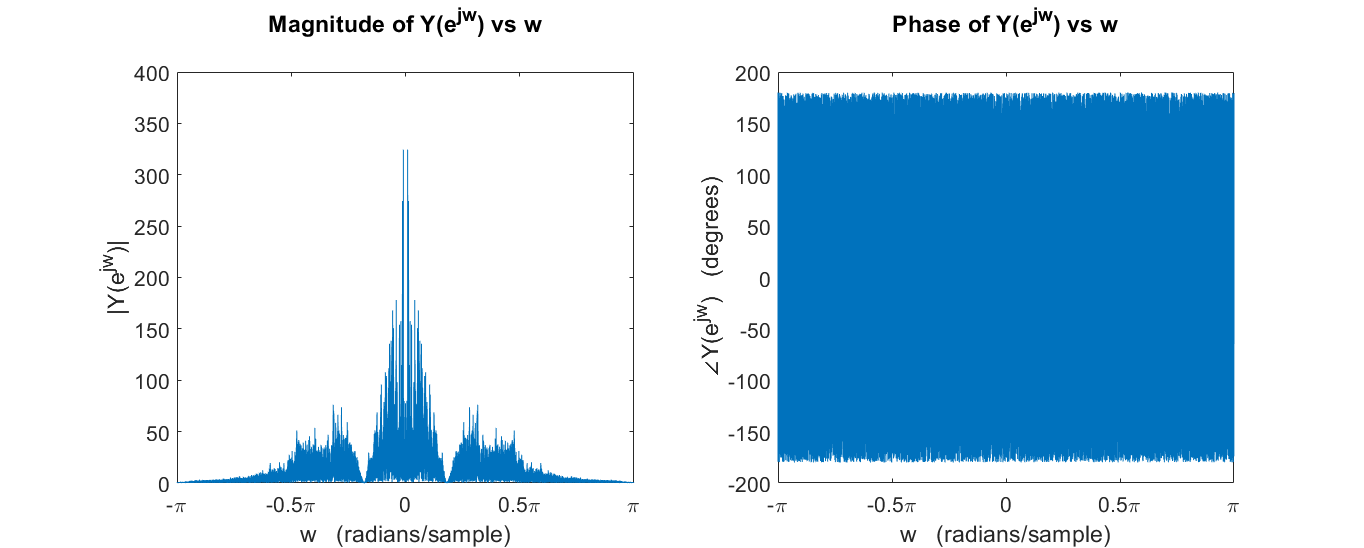

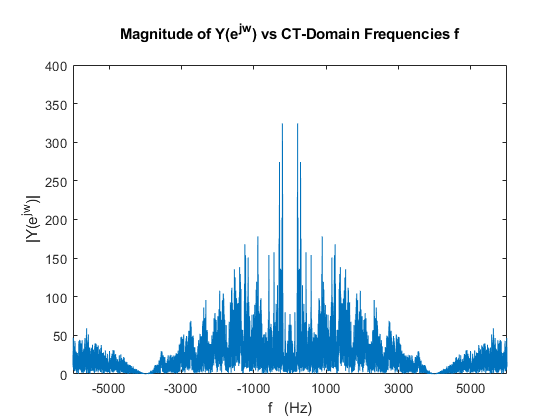


% define Notch Filter system's CCDE coefficients
b = [0.875 -1.4734 0.875];
a = [1 -1.263 0.5625];

% assuming zero initial conditions (rest)
N_aux = zeros(1, length(a)-1);
M_init = zeros(1, length(b)-1);

% compute system output y[n], with input = decimated sound data xd[n],
% using get_system_out()
[y, ny] = get_system_out(b, a, xd, N_aux, M_init);
duration = (length(y)-1)/Fs;

% get and play the audio y(t) using sound command, using Fs/M
sound(y, Fs/M);

% pause execution while the sound is playing
pause(duration);

% plot DTFT of decimated sound data after passing through system (DTFT of y[n])

% initialize frequency vector (and other vars) for computing DTFT Y(w)
w = -pi:2*pi/(length(y)-1):pi;              % for 1 period [-pi, pi] or DTFT
f = Fs * w/(2*pi);                          % corresponding CT-domain frequencies

% compute DTFT Y(w) using (chunk-wise) matrix-multipication method,
% since this is a large computation, avoid repeating it if already computed
if isfile("T2_Yw_.mat") load("T2_Yw_.mat"); end
if ~exist('Yw_','var')
    Yw_ = dtft_split(y, ny, w, 750);
    save("T2_Yw_.mat",'Yw_');
end

% obtain magnitude and phase of DTFT Y(w)
Yw_mag_ = abs(Yw_);                         % get the magnitude of Y(w)
Yw_ang_ = angle(Yw_)*180/pi;                % get the phase (angle) of Y(w) in degrees

% plot magnitude and phase of DTFT Y(w) vs w, 
% and magnitude of Y(w) vs CT-domain frequencies f
plotMagPhase(w, Yw_mag_, Yw_ang_, 'Y', f, [0 400]);

***Computations for AA Filter:  ***The length of the decimation filter $h_{\textrm{lp}} \left\lbrack n\right\rbrack$ is $N=23$. At $h_{\textrm{lp}} \left\lbrack n\right\rbrack$ filter stage, the sample arrival rate is $F_s =44100\;\textrm{samples}/\sec$. Given the AA filter's CCDE coefficients $b=\left\lbrace b_0 \;,b_1 \;,\;\ldotp \ldotp \ldotp ,{\;b}_{22} \right\rbrace$ and $a=\left\lbrace 1\right\rbrace$, it will have a CCDE like,


$$x_f \left\lbrack n\right\rbrack \;=\sum_{m\;=\;0}^{22} b_m \;x\left\lbrack n\right\rbrack$$


which is essentially the form used by $\textrm{get}\_\textrm{system}\_\textrm{out}\left(\right)$ to compute $x_f \left\lbrack n\right\rbrack$. This has a total of $23\;\textrm{multiplications}$, and $22\;\textrm{additions}$, per sample of $x_f \left\lbrack n\right\rbrack$, giving a total of,

$23\times 44100\;=\;1014300\;\mathrm{multiplications}$,   and

$\;22\times 44100\;=\;970200\;\mathrm{additions}$   per second.

***Computations for Notch Filter:  ***As discussed in Task 1 Q3, the Notch Filter requires about $5\;\textrm{multiplications}$, and $4\;\textrm{additions}$, per sample of $y\left\lbrack n\right\rbrack$. But after decimation, the sample arrival rate of $x_d \left\lbrack n\right\rbrack$ at the Notch Filter is $F_s /M=44100/4=11025\;\textrm{samples}/\sec$. This leaves us with a total of,

$5\times 11025\;=\;55125\;\mathrm{multiplications}$,   and

$\;\;\;4\times 11025\;=\;44100\;\mathrm{additions}$   per second.

which is a reduction by a factor of 4 compared to the undecimated implementation.

**Question (4):**

Implement an equivalent polyphase-decomposition based decimation system for the given system. 

How many additions and multiplications are required per unit time?

**Answer (4):**

For polyphase implementation of the decimation (AA) filter, it has to be split into $M$ subfilters of the form,


$$e_k \left\lbrack n\right\rbrack \;=\;h\left\lbrack \textrm{nM}+k\right\rbrack \;=\;h_k \left\lbrack \textrm{nM}\right\rbrack$$


where $h\left\lbrack n\right\rbrack =h_{\textrm{lp}} \left\lbrack n\right\rbrack$ designed previously, and $k=\left\lbrack 0,\;1,\;\ldotp \ldotp ,\;M-1\right\rbrack$. This allows to implement the decimation system as follows,

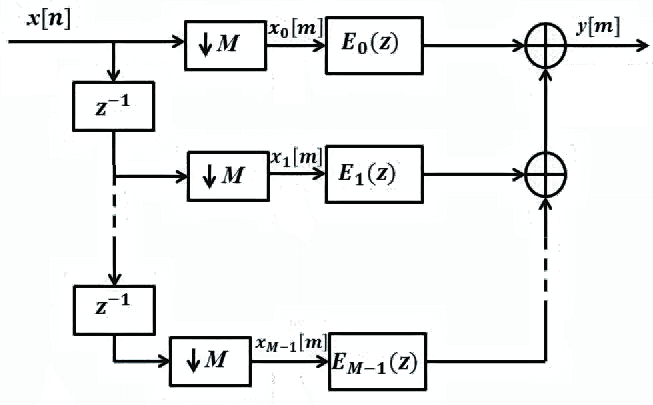

For this, we define the required $e_k \left\lbrack n\right\rbrack$ and downsampled+shifted $x\left\lbrack n\right\rbrack$ sequences, convolve the respective ones, and sum the results to obtain decimated $x_d \left\lbrack n\right\rbrack$. The code implementing this polyphase-decomposition based decimation system starts below.

% <task> implement polyphase-decomposition based decimation system 

xd_nonpolyphase = xd;                       % keep old xd[n] for comparison        
M = 4;                                      % decimation factor

xdM = cell(1, M);                           % to hold M (partial) xd[n] sequences
nxdM = cell(1, M);

xd = zeros(1, length(x)/M);                 % to hold final decimated sequence
nxd = 0:(length(xd)-1);

% decomposition into M branches
for k=0:(M-1)
    
    % define ek[n] = hlp[nM+k] (advance by k, scale by M)
    ek = dnsample(hlp, nhlp, M, -k);
    
    % define xk[n] = x[nM-k] (delay by k, scale by M)
    [xk, nxk] = dnsample(x, n, M, k, 0);
    
    % have xk[n] start at n=0
    xk = xk(find(n==0, 1):end);
    nxk = nxk(find(n==0, 1):end);
        
    % CCDE coefficients for ek (decomposed AA filter)
    b = ek;
    a = [1];
    
    % assuming zero initial conditions (rest)
    N_aux = zeros(1, length(a)-1);
    M_init = zeros(1, length(b)-1);
    
    % pass xk[n] through ek[n] using get_system_out()
    [xdM{k+1}, nxdM{k+1}] = get_system_out(b, a, xk, N_aux, M_init);
    
    % add this partial result to total xd[n]
    [xd, nxd] = sigadd(xd, nxd, xdM{k+1}, nxdM{k+1});
    
end

% clip result to expected size of decimated sequence
xd = xd(1:length(x)/M);
nxd = nxd(1:length(xd));

% compare result xd[n] with non-polyphase implementation of decimation (Q3)
if isequal(round(xd, 10), round(xd_nonpolyphase, 10))
    disp(['Result of polyphase implmentation of decimation' ...
        ' matches with the non-polyphase implementation in Q3.'])
end

Result of polyphase implmentation of decimation matches with the non-polyphase implementation in Q3.



% compute and plot DTFT of xd[n]

% initialize frequency vector (and other vars) for computing DTFT X(w)
w = -pi:2*pi/(length(xd)-1):pi;             % for 1 period [-pi, pi] or DTFT

% compute DTFT Xd(w) using (chunk-wise) matrix-multipication method,
% since this is a large computation, avoid repeating it if already computed
if isfile("T2_Xdw_.mat") load("T2_Xdw_.mat"); end
if ~exist('Xdw_','var')
    Xdw_ = dtft_split(xd, nxd, w, 750);
    save("T2_Xdw_.mat",'Xdw_');
end

% obtain magnitude and phase of DTFT Xd(w)
Xdw_mag_ = abs(Xdw_);                       % get the magnitude of Xd(w)
Xdw_ang_ = angle(Xdw_)*180/pi;              % get the phase (angle) of Xd(w) in degrees

% plot magnitude and phase of DTFT Xd(w) vs w
plotMagPhase(w, Xdw_mag_, Xdw_ang_, 'X_d');

Just as in Q3,  after this decimation by $M=4$, the tone has shifted to DT frequency $\omega =4\left(\pm \;0\ldotp 04535\pi \right)$ $=\pm \;0\ldotp 1814\pi \;\mathrm{rad}/\sec$. Which, as calculated for Q3, results in following CCDE coefficients for Notch Filter $H\left(z\right)$:


$$\begin{array}{l}
b\;=\;\left\lbrace \;0\ldotp 875,\;-1\ldotp 4734,\;0\ldotp 875\;\right\rbrace \\
a\;=\;\left\lbrace \;1,\;-1\ldotp 263,\;0\ldotp 5625\;\right\rbrace 
\end{array}$$



% define Notch Filter system's CCDE coefficients
b = [0.875 -1.4734 0.875];
a = [1 -1.263 0.5625];

% assuming zero initial conditions (rest)
N_aux = zeros(1, length(a)-1);
M_init = zeros(1, length(b)-1);

% compute output y[n], with input = decimated sound data xd[n], using get_system_out()
[y, ny] = get_system_out(b, a, xd, N_aux, M_init);

% get and play the audio y(t) using sound command, using Fs/M
sound(y, Fs/M);                             pause((length(y)-1)/Fs);

% plot DTFT of decimated sound data after passing through system (DTFT of y[n])

% initialize frequency vector (and other vars) for computing DTFT Y(w)
w = -pi:2*pi/(length(y)-1):pi;              % for 1 period [-pi, pi] or DTFT
f = Fs * w/(2*pi);                          % corresponding CT-domain frequencies

% compute DTFT Y(w) using (chunk-wise) matrix-multipication method
if isfile("T2_Yw__.mat") load("T2_Yw__.mat"); end
if ~exist('Yw__','var')
    Yw__ = dtft_split(y, ny, w, 750);       save("T2_Yw__.mat",'Yw__');
end

% obtain magnitude and phase of DTFT Y(w)
Yw_mag__ = abs(Yw__);                       % get the magnitude of Y(w)
Yw_ang__ = angle(Yw__)*180/pi;              % get the phase (angle) of Y(w) in degrees

% plot magnitude and phase of DTFT Y(w) vs w, 
% and magnitude of Y(w) vs CT-domain frequencies f
plotMagPhase(w, Yw_mag__, Yw_ang__, 'Y', f, [0 400]);

***Computations for AA Filter:  ***The length of decimation filter $h_{\textrm{lp}} \left\lbrack n\right\rbrack$ is $N=23$. But upon decomposition, for a branch $k$, $e_k \left\lbrack n\right\rbrack$ has the length $N/M=23/4$, with a decimated version of $x\left\lbrack n\right\rbrack$ arriving to it at a rate of $F_s /M$. This gives ~ $\left(N/M\right)\left(F_s /M\right)\;\mathrm{multiplications}$ and $\left(N/M-1\right)\left(F_s /M\right)\;\textrm{additions}$ per second per branch. As there are $M$ branches, we have in total $\left(N/M\right)\left(F_s \right)\;\textrm{multiplications}$ and $\left(N/M-1\right)\left(F_s \right)\;\textrm{additions}$ per second, that is,

$\;\;\;\;\;\;\;\;\;\frac{N}{M}\times F_s \;=\;\frac{23}{4}\times 44100\;=\;23\times 11025\;=\;253575\;\mathrm{multiplications}$,   and

$\left(\frac{N}{M}-1\right)\times F_s \;=\;\frac{19}{4}\times 44100\;=\;19\times 11025\;=\;209475\;\mathrm{additions}$   per second.

which is a reduction by a factor of about 4 compared to the non-polyphase implementation.

***Computations for Notch Filter:  ***The computations for the Notch Filter remain the same as in Q3, which are,

$5\times 44100/4=\;55125\;\mathrm{multiplications}$,          and          $\;4\times 44100/4=\;44100\;\mathrm{additions}$,          per second.

**Question (5):**

Do you see any gains in number of computations? 

**Answer (5):**

The number of computations for the Notch Filter reduced by a factor of $M=4$ by using decimation of $x\left\lbrack n\right\rbrack$ before applying the Notch Filter. Furthermore, the computations for the decimation filter also reduced by roughly $M=4$ upon using polyphase implementation of decimation. A summary is given in folllowing tables.


$$\matrix{\cr
\text{ }    	& \text{Decimation Filter} 	& \text{Notch Filter}	\cr
& \text{--------------------------------------------} & \text{-----------------------------------------}  \cr
\text{Method} & \matrix{\times &&&&&&&& +} & \matrix{\times &&&&&&&& +}  \cr
\text{----------------------------}  & \text{--------------------------------------------} & \text{-----------------------------------------}  \cr
\text{Undecimated}			&  \matrix{- &&&&&&&& -}			& \matrix{(N_n)F_s &&&&& (N_n-1)F_s}			\cr
\text{Decimated}			& \matrix{(N_d)F_s &&&& (N_d-1)F_s} 			& \matrix{(N_n)F_s/M &&& (N_n-1)F_s/M}				\cr
\text{Decimated - Polyphase}			& \matrix{(N_d/M)F_s && (N_d/M-1)F_s} 			& \matrix{(N_n)F_s/M &&& (N_n-1)F_s/M}					\cr
}
$$



$$\matrix{\cr
\text{ }    	& \text{Decimation Filter} 	& \text{Notch Filter}	\cr
& \text{--------------------------------------------} & \text{-----------------------------------------}  \cr
\text{Method} & \matrix{\times &&&&&&&& +} & \matrix{\times &&&&&&&& +}  \cr
\text{----------------------------}  & \text{--------------------------------------------} & \text{-----------------------------------------}  \cr
\text{Undecimated}			&  \matrix{- &&&&&&&& -}			& \matrix{220500 &&&&& 176400}			\cr
\text{Decimated}			& \matrix{1014300 &&&&& 970200} 			& \matrix{55125 &&&&&& 44100}				\cr
\text{Decimated - Polyphase}			& \matrix{253575 &&&& \ \ 209475} 			& \matrix{55125 &&&&&& 44100}					\cr
}$$


## Functions used in the tasks

### dtft_split()

Used in Task 1 (Q1, Q2) and Task 2 (Q3, Q4) — to compute DTFT of large sequences by $\omega$-chunk-wise matrix-multiplication method.

***Note:****  To identify the sharp tone, *$\omega$* array size should be comparable to that of audio sequence *$x\left\lbrack n\right\rbrack$ $\left(=255864\;\mathrm{samples}\right)$*, i.e. *$\Delta \omega \approx 2\pi /\left(\mathrm{length}\left(x\right)-1\right)$*. Which means, size of matrix *$n^{\prime } \;\omega$*, required for *$X\left(\omega \right)=x\;\exp \left(-1i\;\;n\prime \;\omega \right)$* one-line computation, would be *$\approx 255864\times 255864$* doubles *$\approx 488\;\mathrm{GiB}$ *for *$64$*-bit double values. Hence the need to split *$\omega$*-values into chunks for peice-wise computation of DTFT.*

% <function> 
% computes DTFT of large sequences by splitting the matrix-multiplication method:
%               Xw = x * exp(-1i * n' * w);
% over chunks of w-values, to be able to hold the n'*w matrix in memory.
%
% <syntax>
% Xw = dtft_split(x, n, w, <wsplit>)
%
% <I/O>
% Xw = output DTFT sequence over range w
% x = DT sequence over range n
% w = DT frequencies array
% wsplit = number to w values to include in one chunk of computation

function Xw = dtft_split(x, n, w, wsplit)

    if ~(nargin==4); wsplit = 750; end
    if wsplit <= 0
        Xw = x * exp(-1i * n' * w);     % one-line matrix-mult. solution
    else
        dtft_split_routine();           % call chunk-wise matrix-mult. method
    end
    
    function dtft_split_routine
        % compute DTFT X(w) using (chunk-wise) matrix-multipication method
        Xw = zeros(1, length(w));
        wlen = length(w);
        p_b = 1:wsplit:wlen;  p_e = [wsplit:wsplit:wlen, wlen];
        for i   = 1:ceil(wlen/wsplit)
            Xw( p_b(i):p_e(i) ) = x * exp(-1i * n' * w( p_b(i):p_e(i) ));
        end
    end

end

### dnsample()

Used in Task 2 (Q3, Q4) — to downsample (throw away samples of) a given sequence by factor of M, and to introduce an optional shift before downsampling.

% <function>
% downsamples sequence x[n] by a factor M to obtain y[n] = x[nM], adds shift 
% before downsampling if optional input 'd' provided, extends sequence to 
% include n=r data-point before downsampling if optional input 'r' provided.
%
% <syntax>
% [y, m] = dnsample(x, n, M, <d>, <r>)
%
% <I/O>
% y = output (dilated) sequence = x[nM]
% x = input sequence x[n]
% M = decimation factor
% d = optional delay by 'd' samples before downsampling
% r = n-axis point to include in sequence before downsampling

function [y, m] = dnsample(x, n, M, d, r)
    
    % M must be a non-zero positive integer
    if (M <= 0)
        error('M must be a non-zero positive number');
    end
    M = round(M, 0);
    
    % check for shift parameter
    if nargin >= 4
        n = n + d;
    end

    % extend to include n=r, if requested
    if nargin == 5
        if n(end) < r
            n_end = n(end);
            n = [n n_end+1:r];
            x = [x zeros(1, r-n_end)];
        elseif n(1) > r
            n_start = n(1);
            n = [r:n_start-1 n];
            x = [zeros(1, n_start-r) x];
        end
    end
    
    % mod(a, b): nonzero results are always negative if the divisor is negative
    %            and always positive if the divisor is positive
    diff = mod(n(1), M);
    
    % keeping y[0]=x[0.M]=x[0], beginning m value should be
    if diff == 0
        m_b_inx = 1;                        % starts at same value as in n
    else 
        m_b = n(1) + M - mod(n(1), M);
        m_b_inx = find(n == m_b, 1);        % index in n of beginning m value
    end
    
    % decimate x[n] to get y[n]=x[nM]
    m = n(m_b_inx:M:end)/M;
    y = x(m_b_inx:M:end);
    
end

### sigadd()

Used in Task 2 (Q4) — to add two sequences of different lengths.

% <function> 
% implements y(n) = x1[n]+x2[n], for different sized x1 and x2.
%
% <syntax>
% [y, n] = sigadd(x1, n1, x2, n2)
%
% <I/O>
% y = sum sequence over n, which includes n1 and n2
% x1 = first sequence over n1
% x2 = second sequence over n2 (n2 can be different from n1)

function [y, n] = sigadd(x1, n1, x2, n2)

    % n should be from min(n1, n2) to max(n1, n2)
    n = min(min(n1), min(n2)) : max(max(n1), max(n2));
    
    % for storing x1 and x2 in array spanning length of y
    x1_ = zeros(1, length(n)); 
    x2_ = x1_;
    
    % copy x1 into x1_ at its corresponding n values (from n1)
    x1_( find( (n>=min(n1)) & (n<=max(n1)) == 1 ) ) = x1;
    
    % copy x2 into x2_ at its corresponding n values (from n2)
    x2_( find( (n>=min(n2)) & (n<=max(n2)) == 1 ) ) = x2;

    y = x1_ + x2_;

end

### plotMagPhase()

Used in Task 1 (Q1, Q2) and Task 2 (Q3, Q4) — to plot given magnitude and phase response against $\omega$, and magnitude against $f$ (CT-domain frequencies) if $f$-axis provided.

% <function> 
% plots given magnitude and phase response against given w values, and 
% magnitude against f (CT-domain frequencies) if f-axis array provided.
%
% <syntax>
% plotMagPhase(w, Xw_mag, Xw_ang, X, <f>, <mag_ylim>)
%
% <I/O>
% w = DT frequencies array [-pi, pi]
% Xw_mag = DTFT magnitude
% Xw_ang = DTFT phase
% X = name of DTFT for label/title in plot
% f = optional CT frequencies array
% mag_ylim = optional y-axis limit for DTFT magnitude

function plotMagPhase(w, Xw_mag, Xw_ang, X, f, mag_ylim)
    
    % plot magnitude and phase of DTFT X(w)
    fig = figure; 
    set(fig,'Units','normalized','Position',[0 0 1.4 1]);

    % plot magnitude of X(w) vs w
    subplot(1, 2, 1);
    plot(w, Xw_mag);
    xlabel('w   (radians/sample)'); 
    ylabel(['|',X,'(e^{jw})|']);
    % check and set optional y-axis limit
    if nargin == 6
        ylim(mag_ylim); 
    end
    title({['Magnitude of ',X,'(e^{jw}) vs w'];''}, 'FontSize', 16);
    setDTFTradialAxis(1); 
    ax = gca; 
    ax.FontSize = 16;
    
    % plot phase of X(w) vs w
    subplot(1, 2, 2);
    plot(w, Xw_ang);
    xlabel('w   (radians/sample)'); 
    ylabel(['∠',X,'(e^{jw})   (degrees)']);
    title({['Phase of ',X,'(e^{jw}) vs w'];''}, 'FontSize', 16);
    setDTFTradialAxis(1); 
    ax = gca; 
    ax.FontSize = 16;
    
    if nargin >= 5
        % plot magnitude of X(w) vs CT-domain frequencies f
        fig = figure;
        plot(f, Xw_mag);
        xlabel('f   (Hz)'); ylabel(['|',X,'(e^{jw})|']);
        xlim([-6e3 6e3]); xticks(-5e3:2e3:5e3);
        % check and set optional y-axis limit
        if nargin == 6
            ylim(mag_ylim); 
        end
        title({'';['Magnitude of ',X,'(e^{jw}) vs CT-Domain Frequencies f'];''});
    end
    
end

;